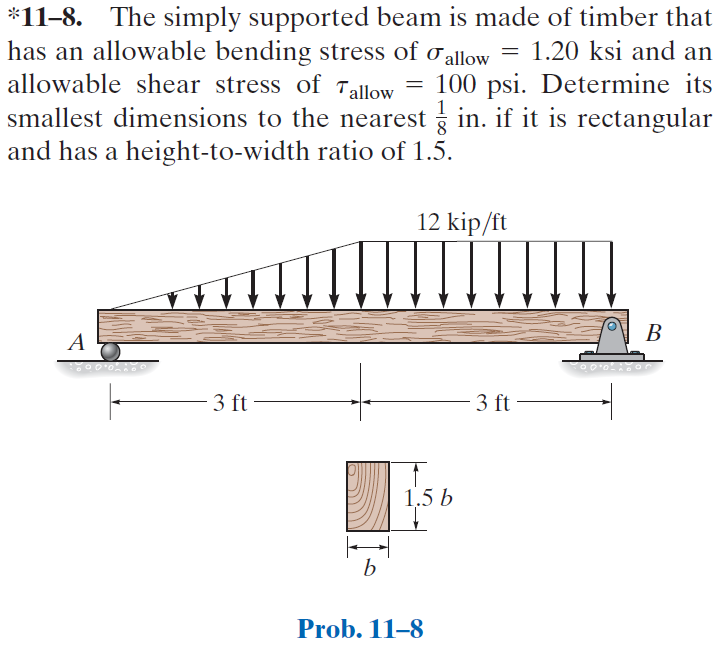

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-8P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-8P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
w1 = findpoly(1, 'thru', [0 0], 'thru', [3*u.ft -12*u.kip/u.ft]);
w2(x) = -12*u.kip/u.ft;
B_min = default_struct('bending', 'shear', 'limit');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.ft);
b = b.add('distributed', 'force', w1, [0 3]*u.ft);
b = b.add('distributed', 'force', w2, [3 6]*u.ft, [false true]);
b.L = 6*u.ft;

# section properties

B = sym('B', 'positive');
H(B) = 1.5*B;
b.I = B*H^3/12;
A = B*H;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{8\,x\,\left(2\,x^{4}-210\,x^{2}\,{\mathrm{ft}}^{2}+5049\,{\mathrm{ft}}^{4}\right)}{135\,B^{4}\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 3\,\mathrm{ft}\\ \frac{8\,\left(x-6\,\mathrm{ft}\right)\,\left(-10\,x^{3}+70\,x^{2}\,\mathrm{ft}+240\,x\,{\mathrm{ft}}^{2}+27\,{\mathrm{ft}}^{3}\right)}{45\,B^{4}\,\text{E}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{8\,\left(10\,x^{4}-630\,x^{2}\,{\mathrm{ft}}^{2}+5049\,{\mathrm{ft}}^{4}\right)}{135\,B^{4}\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -\frac{8\,\left(40\,x^{3}-390\,x^{2}\,\mathrm{ft}+360\,x\,{\mathrm{ft}}^{2}+1413\,{\mathrm{ft}}^{3}\right)}{45\,B^{4}\,\text{E}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{x\,\left(63\,{\mathrm{ft}}^{2}-2\,x^{2}\right)}{3}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -3\,\left(x-6\,\mathrm{ft}\right)\,\left(2\,x-1\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \left(21\,{\mathrm{ft}}^{2}-2\,x^{2}\right)\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -3\,\left(4\,x-13\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -4\,x\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 3\,\mathrm{ft}\\ -12\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 21\,\mathrm{kip}\\ \mathrm{Rb} & 33\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

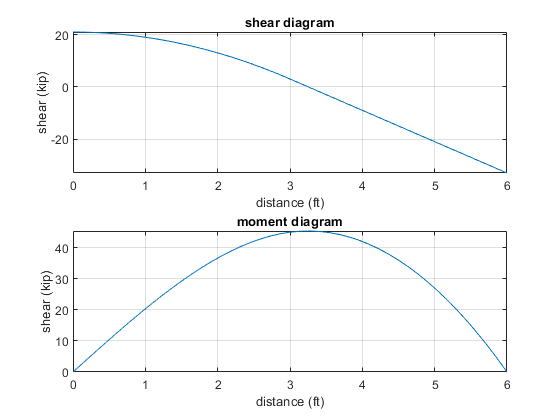

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# maximum loads

assume(0 < x & x < b.L);
xmax = solve(v == 0);
M_max = m(xmax);
M_max_vpa = vpa(M_max) %#ok<NASGU> 

$$M\_max\_vpa = 45.375\,\mathrm{ft}\,\mathrm{kip}$$

V_max = v(b.L)

$$V\_max = -33\,\mathrm{kip}$$

# maximum bending stress

C = H/2;
sigma_max = rewrite(M_max, u.kip*u.in)*C/b.I

$$sigma\_max(B) = \frac{1452}{B^{3}}\,\mathrm{in}\,\mathrm{kip}$$

# maximum shear stress

tau_max = 3*abs(V_max)/(2*A)

$$tau\_max(B) = \frac{33}{B^{2}}\,\mathrm{kip}$$

# minimum beam dimension due to bending

sigma_allow = 1.20*u.ksi;
B_min.bending = solve(sigma_max == rewrite(sigma_allow, [u.kip u.in]));
B_min.bending = simplify(B_min.bending);
B_min_bending = vpa(B_min.bending, 4) %#ok<NASGU> 

$$B\_min\_bending = 10.66\,\mathrm{in}$$

# minimum beam dimension due to shear

tau_allow = 100*u.psi;
B_min.shear = solve(tau_max == rewrite(tau_allow, [u.kip u.in]));
B_min.shear = simplify(B_min.shear);
B_min_shear = vpa(B_min.shear, 4) %#ok<NASGU> 

$$B\_min\_shear = 18.17\,\mathrm{in}$$

# design beam dimension

B_min_vals = [B_min.bending B_min.shear];
loc = (sigma_max(B_min_vals) <= sigma_allow) & ...
      (tau_max(B_min_vals) <= tau_allow);
B_min.design = B_min_vals(isAlways(loc));
B_min_design = vpa(B_min.design, 4) %#ok<NASGU> 

$$B\_min\_design = 18.17\,\mathrm{in}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;
clear M_max_vpa;
clear B_min_bending;
clear B_min_shear;
clear B_min_vals loc B_min_design;